% MATLAB Script for High-Quality Plotting of Wind Power Data
% This script creates publication-quality plots at 800 DPI from CSV files

% Set default figure properties for high-quality output
set(0, 'DefaultFigureRenderer', 'painters'); % Vector renderer for better quality
set(0, 'DefaultFigureColor', 'w'); % White background
set(0, 'DefaultAxesFontSize', 14); % Larger font size
set(0, 'DefaultAxesLineWidth', 1.5); % Thicker axes lines
set(0, 'DefaultLineLineWidth', 1.5); % Thicker plot lines

% Common figure size (in inches)
figWidth = 10;
figHeight = 6;

% Define custom color scheme
colorNormal = [0.0000, 0.4470, 0.7410]; % Blue
colorAnomaly = [0.8500, 0.3250, 0.0980]; % Red
colorTrend = [0.4660, 0.6740, 0.1880]; % Green
colorSeasonal = [0.9290, 0.6940, 0.1250]; % Yellow
colorResidual = [0.4940, 0.1840, 0.5560]; % Purple

%% 1. Plot Power vs Time with Anomalies
% Load power vs. time data
fprintf('Loading power vs. time data...\n');

Loading power vs. time data...


powerTimeData = readtable("D:\Downloads\power_vs_time (1).csv");

% Convert DateTime to MATLAB datetime format
if isa(powerTimeData.DateTime, 'datetime')
    timeData = powerTimeData.DateTime;
else
    timeData = datetime(powerTimeData.DateTime);
end

% Create figure
figure('Position', [100, 100, figWidth*100, figHeight*100], 'Units', 'normalized');

% Plot normal points
normalIdx = powerTimeData.IsAnomaly == 0;
plot(timeData(normalIdx), powerTimeData.Power(normalIdx), 'Color', colorNormal, 'LineWidth', 1.5);
hold on;

% Plot anomalies
anomalyIdx = powerTimeData.IsAnomaly == 1;
scatter(timeData(anomalyIdx), powerTimeData.Power(anomalyIdx), 60, colorAnomaly, 'filled', 'MarkerEdgeColor', 'k');

% Customize plot
grid on;
box on;
%title('Wind Power Output Over Time with Detected Anomalies', 'FontSize', 18, 'FontWeight', 'bold');
xlabel('Time', 'FontSize', 24, 'FontWeight', 'normal');
ylabel('Power (kW)', 'FontSize', 24, 'FontWeight', 'normal');
legend('Power Output', 'Anomalies', 'Location', 'northeast', 'FontSize', 14);

% Adjust axis limits for better visualization
ylim([min(powerTimeData.Power)*0.9, max(powerTimeData.Power)*1.1]);
axis padded;
ax.Position = [0.10  0.13  0.87  0.80];

% Save figure with high resolution
fprintf('Saving power vs. time plot at 800 DPI...\n');

Saving power vs. time plot at 800 DPI...


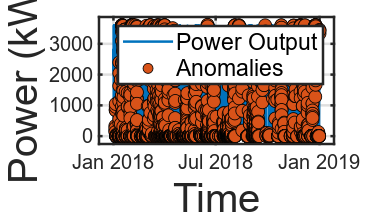

print('-dpng', '-r800', 'power_vs_time_matlab.png');


%% 2. Plot Power vs Wind Speed with Anomalies
% Load power vs. wind speed data
fprintf('Loading power vs. wind speed data...\n');

Loading power vs. wind speed data...


powerWindData = readtable("D:\Downloads\power_vs_wind (1).csv");

% Create figure
figure('Position', [100, 100, figWidth*100, figHeight*100], 'Units', 'normalized');

% Plot normal points
normalIdx = powerWindData.IsAnomaly == 0;
scatter(powerWindData.WindSpeed(normalIdx), powerWindData.Power(normalIdx), 90, colorNormal, 'filled', 'MarkerEdgeColor', 'none', 'MarkerFaceAlpha', 0.7);
hold on;

% Plot anomalies
anomalyIdx = powerWindData.IsAnomaly == 1;
scatter(powerWindData.WindSpeed(anomalyIdx), powerWindData.Power(anomalyIdx), 50, colorAnomaly, 'filled', 'MarkerEdgeColor', 'k');

% Customize plot
grid on;
box on;
%title('Wind Power vs. Wind Speed with Detected Anomalies', 'FontSize', 18, 'FontWeight', 'bold');
xlabel('Wind Speed (m/s)', 'FontSize', 24, 'FontWeight', 'normal');
ylabel('Power (kW)', 'FontSize', 24, 'FontWeight', 'normal');
legend('Normal Data', 'Anomalies', 'Location', 'northwest', 'FontSize', 14);

% Add theoretical power curve
windSpeeds = linspace(0, max(powerWindData.WindSpeed)*1.1, 100);
rho = 1.225; % Air density (kg/m³)
A = 7854.0;  % Rotor area (m²) for 100m diameter
Cp = 0.4;    % Power coefficient
theoreticalPower = 0.5 * rho * A * Cp * (windSpeeds.^3);
plot(windSpeeds, theoreticalPower, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 2);
legend('Normal Data', 'Anomalies', 'Theoretical Power Curve', 'Location', 'northwest', 'FontSize', 14);

axis padded;
ax.Position = [0.10  0.13  0.87  0.80];
% Save figure with high resolution
fprintf('Saving power vs. wind speed plot at 800 DPI...\n');

Saving power vs. wind speed plot at 800 DPI...


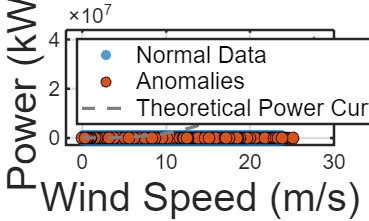

print('-dpng', '-r800', 'power_vs_wind_matlab.png');


%% 3. Plot STL Decomposition
% Load STL decomposition data
fprintf('Loading STL decomposition data...\n');

Loading STL decomposition data...


stlData = readtable("D:\Downloads\stl_decomposition (1).csv");

% Convert DateTime to MATLAB datetime format
if isa(stlData.DateTime, 'datetime')
    timeData = stlData.DateTime;
else
    timeData = datetime(stlData.DateTime);
end

% Create figure
figure('Position', [150, 150, figWidth*120, figHeight*160], 'Units', 'normalized');

% Create subplots
subplot(4, 1, 1);
plot(timeData, stlData.Observed, 'Color', colorNormal, 'LineWidth', 1.5);
title('Observed', 'FontSize', 28, 'FontWeight', 'bold');
grid on;
xlim([min(timeData), max(timeData)]);
ylabel('Power (kW)', 'FontSize', 20);
ax = gca;
set(ax, 'FontSize', 18);

subplot(4, 1, 2);
plot(timeData, stlData.Trend, 'Color', colorTrend, 'LineWidth', 1.5);
title('Trend', 'FontSize', 28, 'FontWeight', 'bold');
grid on;
xlim([min(timeData), max(timeData)]);
ylabel({'Component', 'Value'}, 'FontSize', 14);
ax = gca;
set(ax, 'FontSize', 18);

subplot(4, 1, 3);
plot(timeData, stlData.Seasonal, 'Color', colorSeasonal, 'LineWidth', 1.5);
title('Seasonal', 'FontSize', 28, 'FontWeight', 'bold');
grid on;
xlim([min(timeData), max(timeData)]);
ylabel({'Component', 'Value'}, 'FontSize', 14);
ax = gca;
set(ax, 'FontSize', 18);

subplot(4, 1, 4);
plot(timeData, stlData.Residual, 'Color', colorResidual, 'LineWidth', 1.5);
title('Residual', 'FontSize', 28, 'FontWeight', 'bold');
grid on;
xlim([min(timeData), max(timeData)]);
xlabel('Time', 'FontSize', 32, 'FontWeight', 'bold');
ylabel({'Component', 'Value'}, 'FontSize', 14);
ax = gca;
set(ax, 'FontSize', 18);

% Adjust spacing between subplots
%sgtitle('STL Decomposition of Wind Power Data', 'FontSize', 18, 'FontWeight', 'bold');
ax = gca;
set(ax, 'FontSize', 18);
set(gcf, 'Position', [150, 150, figWidth*100, figHeight*160]);

% Save figure with high resolution
fprintf('Saving STL decomposition plot at 800 DPI...\n');

Saving STL decomposition plot at 800 DPI...


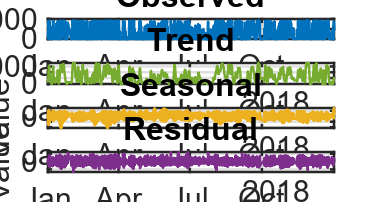

print('-dpng', '-r800', 'stl_decomposition_matlab.png');


%% Additional Quality Enhancements
% Create a combined plot for presentations
figure('Position', [100, 100, figWidth*150, figHeight*100], 'Units', 'normalized');

% Power vs Time with Anomalies (simplified)
subplot(1, 2, 1);
plot(timeData(normalIdx), powerTimeData.Power(normalIdx), 'Color', colorNormal, 'LineWidth', 1.5);
hold on;
scatter(timeData(anomalyIdx), powerTimeData.Power(anomalyIdx), 60, colorAnomaly, 'filled', 'MarkerEdgeColor', 'k');
grid on;
title('Power Output Over Time', 'FontSize', 16, 'FontWeight', 'bold');
xlabel('Time', 'FontSize', 14);
ylabel('Power (kW)', 'FontSize', 14);
legend('Normal', 'Anomalies', 'Location', 'northeast', 'FontSize', 12);

% Power vs Wind Speed (simplified)
subplot(1, 2, 2);
scatter(powerWindData.WindSpeed(normalIdx), powerWindData.Power(normalIdx), 40, colorNormal, 'filled', 'MarkerFaceAlpha', 0.7);
hold on;
scatter(powerWindData.WindSpeed(anomalyIdx), powerWindData.Power(anomalyIdx), 60, colorAnomaly, 'filled', 'MarkerEdgeColor', 'k');
plot(windSpeeds, theoreticalPower, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 2);
grid on;
title('Power vs. Wind Speed', 'FontSize', 16, 'FontWeight', 'bold');
xlabel('Wind Speed (m/s)', 'FontSize', 14);
ylabel('Power (kW)', 'FontSize', 14);
legend('Normal', 'Anomalies', 'Theoretical', 'Location', 'northwest', 'FontSize', 12);

% Save combined figure with high resolution
fprintf('Saving combined plot at 800 DPI...\n');

Saving combined plot at 800 DPI...


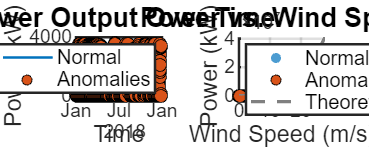

print('-dpng', '-r800', 'combined_plots_matlab.png');


fprintf('All plots generated successfully at 800 DPI.\n');

All plots generated successfully at 800 DPI.
